# Análisis de Fourier

## Función periódica 

**Def.** Una función periódica $f(t)$ con periodo $\tau$ es una función que cumple $f(t+\tau)=f(t)$ para todo $t$.

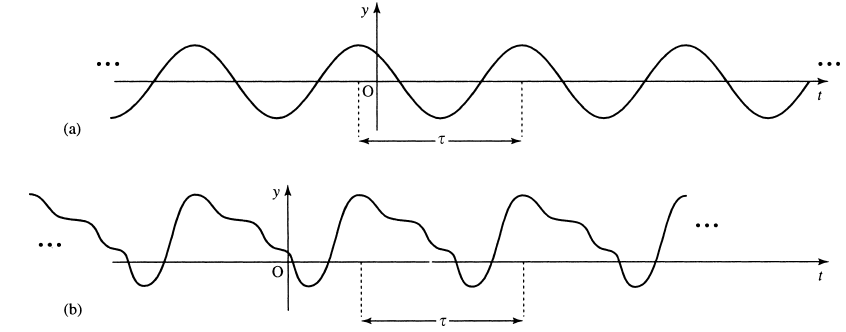

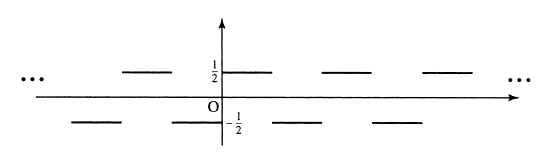

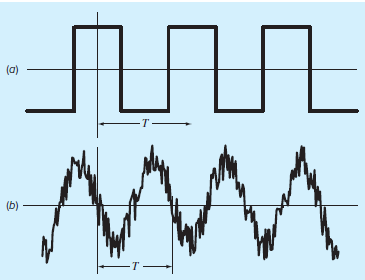

El término fundamental de este tipo de ecuaciones es de la forma

$f (t) = A_0 + C_1cos(\omega_0t + \theta)$  ... (1)

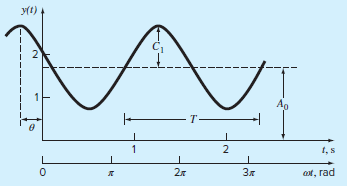

- El valor promedio por encima del eje de las abscisas $A_0$.

- La amplitud de la oscialación $C_1$.

- La frecuencia angula $\omega_0$ que esta relacionada con la frecuencia y el periodo de la forma $\omega_0=2\pi f=2\pi\frac{1}{T}$.

- La fase o el ángulo de desplazamiento $\theta$ que desplaza toda la curva sobre la horizontal.

La ecuación (1) también trae la información de una sinusoidal* (ejercicio 1. Hint: usa el coseno de la suma de ángulos)*. De tal forma que podemos expresar esta ecuación de la forma 

$f(t) = A_0 + A_1cos(\omega_0 t ) + B_1sen(\omega_0 t ) + e$   ...   (2)

que es posible linealizar con la forma $y = a_0z_0 + a_1z_1 + a_2z_2 + \cdot  \cdot  \cdot  + a_mz_m + e$ en un espacio de $m$ dimensiones y sobre la cual es posible aplicar **mínimos cuadrados** para ajustar una recta; donde $z_0=1$, $z_1=cos(\omega_0t)$, $z_2=sen(\omega_0t)$ y todas las demas $z_3=...=z_m=0$.

Los coeficientes son:


$$A_0=\frac{\sum_i f(t_i)}{N}$$



$$A_1=\frac{2}{N}\sum_i f(t_i)cos(\omega_0t_i)$$



$$B_1=\frac{2}{N}\sum_i f(t_i)sen(\omega_0t_i)$$


como esta función es peródica, entonces es posible tomar solamente $N$ puntos en el intervalo $\Delta t$ tal que el periodo de la función $T=(N-1)\Delta t$. Es decir, es suficiente estos $N-1$ puntos para poder describir la función por completo.

## Ejemplo

Para la tabla de datos presentada, obtener los coeficientes de Fourier considerando que representan solo un periodo de la función.

clear
clc
close all
% Definir los datos de la tabla como vectores
t = [0; 0.15; 0.30; 0.45; 0.60; 0.75; 0.90; 1.05; 1.20; 1.35];
y = [2.200; 1.595; 1.031; 0.722; 0.786; 1.200; 1.805; 2.369; 2.678; 2.614];
y_cos = [2.200; 1.291; 0.319; -0.223; -0.636; -1.200; -1.460; -0.732; 0.829; 2.114];
y_sen = [0.000; 0.938; 0.980; 0.687; 0.462; 0.000; -1.061; -2.253; -2.547; -1.536];

% Crear una tabla con los datos
tablaDatos = table(t, y, y_cos, y_sen, ...
    'VariableNames', {'t', 'y', 'y_cos', 'y_sin'});

% Mostrar la tabla
disp('Tabla de datos:');

Tabla de datos:


disp(tablaDatos);

     t        y      y_cos     y_sin 
    ____    _____    ______    ______

       0      2.2       2.2         0
    0.15    1.595     1.291     0.938
     0.3    1.031     0.319      0.98
    0.45    0.722    -0.223     0.687
     0.6    0.786    -0.636     0.462
    0.75      1.2      -1.2         0
     0.9    1.805     -1.46    -1.061
    1.05    2.369    -0.732    -2.253
     1.2    2.678     0.829    -2.547
    1.35    2.614     2.114    -1.536




% Calcular las sumas (última fila de la tabla original)
sumatorias = table(...
    sum(t), sum(y), sum(y_cos), sum(y_sen), ...
    'VariableNames', {'Sum_t', 'Sum_y', 'Sum_y_cos', 'Sum_y_sin'});

disp('Sumatorias:');

Sumatorias:


disp(sumatorias);

    Sum_t    Sum_y    Sum_y_cos    Sum_y_sin
    _____    _____    _________    _________

    6.75      17        2.502        -4.33  




% Calcular coeficientes de Fourier (ejemplo para el primer armónico)
N = length(t);  % Número de muestras
T = (N-1)*(t(2)-t(1));   % Periodo 
omega0 = 2 * pi / T;     % Frecuencia fundamental (ω0 ≈ 4.654 rad/s)

a0 = mean(y);
a1 = 2 * mean(y_cos);
b1 = 2 * mean(y_sen);

% Mostrar resultados
disp('Coeficientes de Fourier (primer armónico):');

Coeficientes de Fourier (primer armónico):


fprintf('a0 = %.4f\n', a0);

a0 = 1.7000


fprintf('a1 = %.4f\n', a1);

a1 = 0.5004


fprintf('b1 = %.4f\n', b1);

b1 = -0.8660


Este ajuste solo considera una única frecuencia de oscilación. Si el fenómeno se pudiese describir con $m$ múltiplos enteros de esta frecuencia entonces la ecuación general del modelo sería


$$f (t) = A_0 + A_1cos(\omega_0 t) + B_1sen(\omega_0 t) + A_2cos(2\omega_0 t) + B_2sen(2\omega_0 t )+ \cdot  \cdot  \cdot  + A_mcos(m\omega_0 t) + B_msen(m\omega_0 t)$$


donde los coeficientes se obtienen por medio de minimos cuadrados como


$$A_0=\frac{\sum_i f(t_i)}{N}$$



$$A_j=\frac{2}{N}\sum_i f(t_i)cos(j\omega_0 t_i)$$



$$B_j=\frac{2}{N}\sum_i f(t_i)sen(j\omega_0 t_i)$$


A los valores $j\omega_0$ donde $j=1,2,...,m$ se le conocen como los armónicos de la función ajustada.

% Datos de la tabla
t = [0; 0.15; 0.30; 0.45; 0.60; 0.75; 0.90; 1.05; 1.20; 1.35];
y = [2.200; 1.595; 1.031; 0.722; 0.786; 1.200; 1.805; 2.369; 2.678; 2.614];

% Parámetros
N = length(t);       % Número de muestras
T = max(t);          % Periodo (T = 1.35)
omega0 = 2 * pi / T; % Frecuencia fundamental (ω0 ≈ 4.654 rad/s)

% Cálculo de términos para el segundo armónico
y_cos2 = y .* cos(2 * omega0 * t);  % y * cos(2ω0t)
y_sin2 = y .* sin(2 * omega0 * t);   % y * sin(2ω0t)

% Coeficientes del segundo armónico
a2 = 2 * mean(y_cos2);
b2 = 2 * mean(y_sin2);

% Mostrar resultados
disp('Coeficientes del segundo armónico:');

Coeficientes del segundo armónico:


fprintf('a2 = %.4f\n', a2);

a2 = 0.5238


fprintf('b2 = %.4f\n', b2);

b2 = -0.0640



% Opcional: Crear tabla para visualización
tablaDatos = table(t, y, y_cos2, y_sin2, ...
    'VariableNames', {'t', 'y', 'y_cos2', 'y_sin2'});
disp('Tabla con términos del segundo armónico:');

Tabla con términos del segundo armónico:


disp(tablaDatos);

     t        y       y_cos2       y_sin2   
    ____    _____    ________    ___________

       0      2.2         2.2              0
    0.15    1.595     0.27697         1.5708
     0.3    1.031    -0.96882        0.35262
    0.45    0.722      -0.361       -0.62527
     0.6    0.786     0.60211       -0.50523
    0.75      1.2     0.91925        0.77135
     0.9    1.805     -0.9025         1.5632
    1.05    2.369     -2.2261       -0.81025
     1.2    2.678     0.46503        -2.6373
    1.35    2.614       2.614    -1.2805e-15




% Sumatorias (verificación)
fprintf('Sum(y_cos2) = %.4f\n', sum(y_cos2));

Sum(y_cos2) = 2.6189


fprintf('Sum(y_sin2) = %.4f\n', sum(y_sin2));

Sum(y_sin2) = -0.3202


Graficando los ajustes

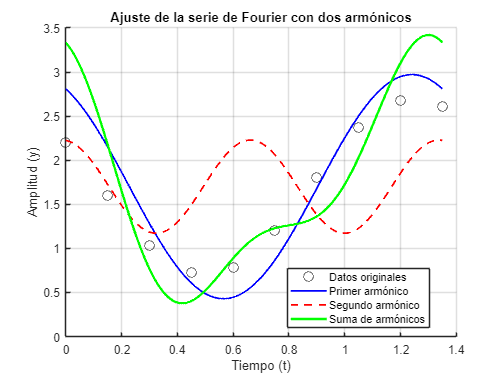

% Datos de la tabla
t = [0; 0.15; 0.30; 0.45; 0.60; 0.75; 0.90; 1.05; 1.20; 1.35];
y = [2.200; 1.595; 1.031; 0.722; 0.786; 1.200; 1.805; 2.369; 2.678; 2.614];

% Parámetros
N = length(t);          % Número de muestras
T = max(t);             % Periodo (T = 1.35)
omega0 = 2 * pi / T;    % Frecuencia fundamental (ω0 ≈ 4.654 rad/s)

% Cálculo de coeficientes del primer armónico
y_cos1 = y .* cos(omega0 * t);
y_sin1 = y .* sin(omega0 * t);
a0 = mean(y);
a1 = 2 * mean(y_cos1);
b1 = 2 * mean(y_sin1);

% Cálculo de coeficientes del segundo armónico
y_cos2 = y .* cos(2 * omega0 * t);
y_sin2 = y .* sin(2 * omega0 * t);
a2 = 2 * mean(y_cos2);
b2 = 2 * mean(y_sin2);

% Crear un vector de tiempo más denso para las curvas suaves
t_dense = linspace(0, T, 1000);

% Ajuste del primer armónico
y_fit1 = a0 + a1 * cos(omega0 * t_dense) + b1 * sin(omega0 * t_dense);

% Ajuste del segundo armónico
y_fit2 = a0 + a2 * cos(2 * omega0 * t_dense) + b2 * sin(2 * omega0 * t_dense);

% Suma de ambos armónicos
y_fit_total = a0 + a1 * cos(omega0 * t_dense) + b1 * sin(omega0 * t_dense) ...
              + a2 * cos(2 * omega0 * t_dense) + b2 * sin(2 * omega0 * t_dense);

% Graficar los datos y los ajustes
figure;
hold on;
grid on;

% Datos originales
plot(t, y, 'ko', 'MarkerSize', 8, 'DisplayName', 'Datos originales');

% Ajuste del primer armónico
plot(t_dense, y_fit1, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Primer armónico');

% Ajuste del segundo armónico
plot(t_dense, y_fit2, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Segundo armónico');

% Suma de ambos armónicos
plot(t_dense, y_fit_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Suma de armónicos');

% Configuración del gráfico
xlabel('Tiempo (t)');
ylabel('Amplitud (y)');
title('Ajuste de la serie de Fourier con dos armónicos');
legend('Location', 'best');
hold off;

Las series de Fourier no solo sirven para ajustar datos que pueden tener una periodicidad. También se ocupa para transformar funciones continuas $f(t)$ que parecen ser periodicas a funciones seno y coseno de la forma


$$f (t) = a_0 + \sum_{k=1}^{\infty}[a_kcos(k\omega_0 t ) + b_ksen(k\omega_0 t )]$$


donde de nuevo los valor $k$ definen los armónicos. En este caso la evaluación de cada coeficiente se realiza para $f(t)$ con el valor de $t$ para el intervalo correspondiente.

Para poder evaluar los coeficientes necesitamos en cálculo contínuo de las sumas, por lo que las coeficientes ahora son usando una integral en lugar de una suma sobre el periodo de tiempo:


$$a_0=\frac{2}{T}\int_0^Tf(t)dt$$



$$a_k=\frac{2}{T}\int_0^Tf(t)cos(k\omega_0t)dt$$



$$b_k=\frac{2}{T}\int_0^Tf(t)sen(k\omega_0t)dt$$


## Ejemplo

Una ecuación de onda rectangular se puede describir como


$$f(t)=\left\{ \begin{array}{rr}-1&-T/2<t<-T/4\\
1&-T/4<t<-T/4\\
-1&-T/4<t<-T/2\\
 \end{array} $$


con altura de 2 unidades y periodo $T=2\pi/ \omega_0$.

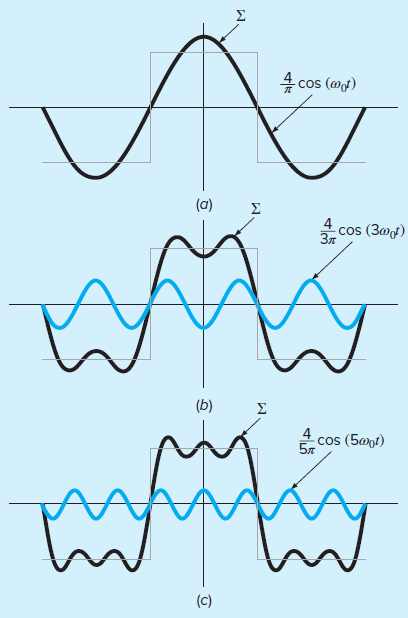

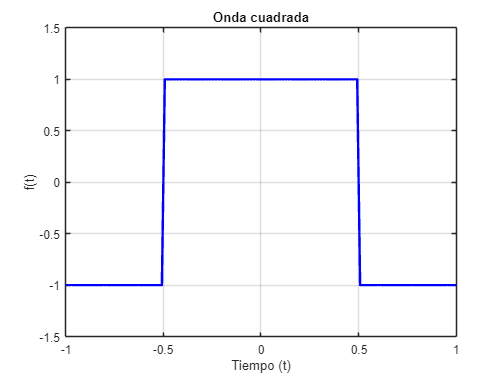

% Definir el periodo T
T = 2;  % Puedes ajustar T según necesites
omega0=2*pi/T;
N = 45; %número de datos
k = 2;  %número de armónicos
% Crear un vector de tiempo para un periodo
t = linspace(-T/2, T/2, N*3);

% Inicializar la función
f = zeros(size(t));

% Definir los intervalos
f(t >= -T/2 & t < -T/4) = -1;
f(t >= -T/4 & t < T/4) = 1;
f(t >= T/4 & t <= T/2) = -1;

% Graficar
figure;
plot(t, f, 'b-', 'LineWidth', 2);
grid on;
xlabel('Tiempo (t)');
ylabel('f(t)');
title('Onda cuadrada');
ylim([-1.5, 1.5]);  % Ajustar los límites del eje y
xlim([-T/2, T/2]);  % Mostrar solo un periodo

a0 = 2/T* trapz(f)

a0 = 0

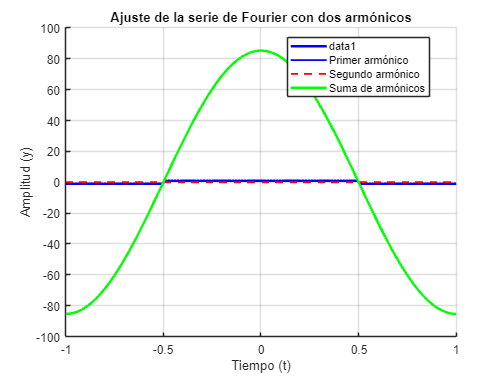

    
    % Coeficientes an y bn
    an = zeros(1, k);
    bn = zeros(1, k);
    
    for n = 1:k
        an(n) = (2/T) * trapz(f.*cos(n*omega0*t));
        bn(n) = (2/T) * trapz(f.*sin(n*omega0*t));
    end
% end

% Ajuste del primer armónico
y_fit1 = a0 + an(1) * cos(omega0 * t) + bn(1) * sin(omega0 * t);

% Ajuste del segundo armónico
y_fit2 = a0 + an(2) * cos(2 * omega0 * t) + bn(2) * sin(2 * omega0 * t);

% Suma de ambos armónicos
y_fit_total = a0 + an(1) * cos(omega0 * t) + bn(1) * sin(omega0 * t) ...
              + an(2) * cos(2 * omega0 * t) + bn(2) * sin(2 * omega0 * t);

% Graficar los datos y los ajustes
figure;
hold on;
grid on;

% Datos originales
plot(t, f, 'b-', 'LineWidth', 2);
% Ajuste del primer armónico
plot(t, y_fit1, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Primer armónico');
% 
% % Ajuste del segundo armónico
plot(t, y_fit2, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Segundo armónico');
% 
% % Suma de ambos armónicos
plot(t, y_fit_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Suma de armónicos');

% Configuración del gráfico
xlabel('Tiempo (t)');
ylabel('Amplitud (y)');
title('Ajuste de la serie de Fourier con dos armónicos');
legend('Location', 'best');
hold off;

# ___________________________________________________________

Las series de Fourier se pueden expresar usando la formaula de Euler 


$$e^{\,\pm \,i\, x}=\text{cos}\,(x)\pm i\,\text{sen}\,(x)$$


sustituyendo esta expresión en la serie de Fourier obtenemos que 


$$f(t)=\sum_{k=-\infty}^{\infty}c_ke^{ik\omega_0t}$$


y donde el coeficiente es


$$c_k=\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}}f(t)e^{-ik\omega_0t}dt$$
